clear all
clc

estatura = table2array(readtable('Datos.xlsx','Range','B2:B207'));
talla = table2array(readtable('Datos.xlsx','Range','C2:C207'));
sexo = string(table2array(readtable('Datos.xlsx','Range','D1:D207')));

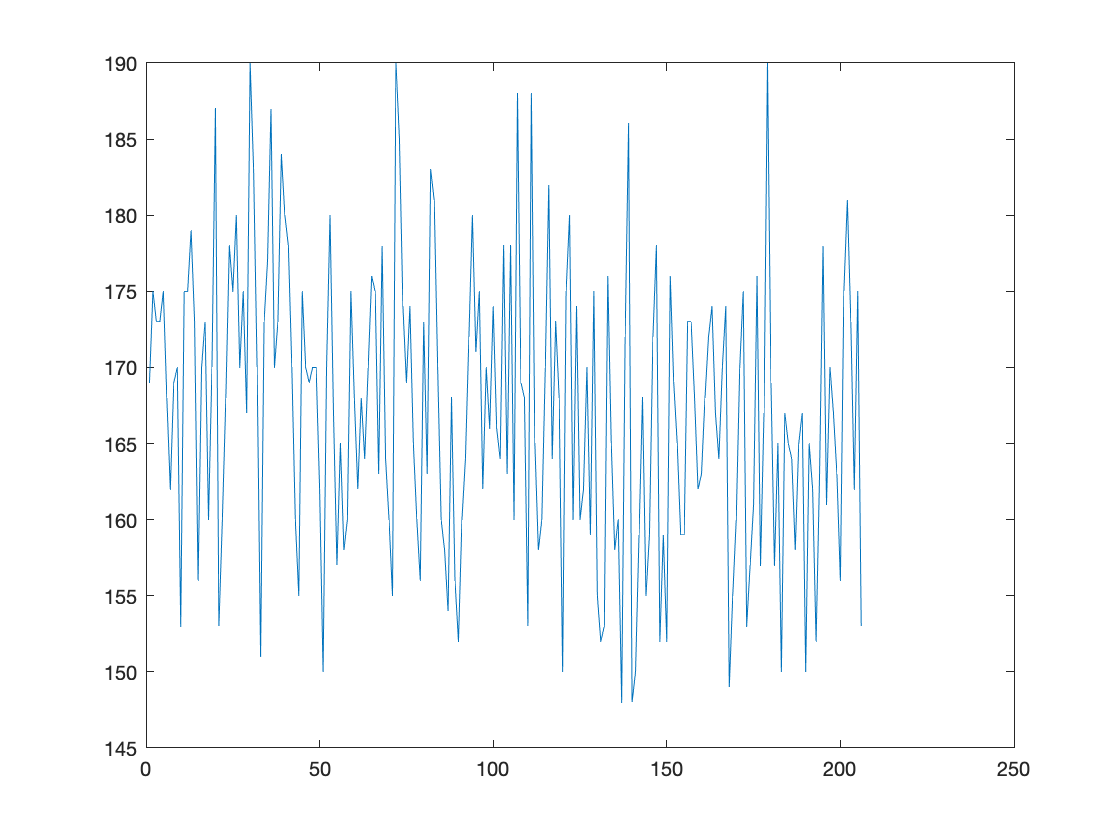

plot(estatura)

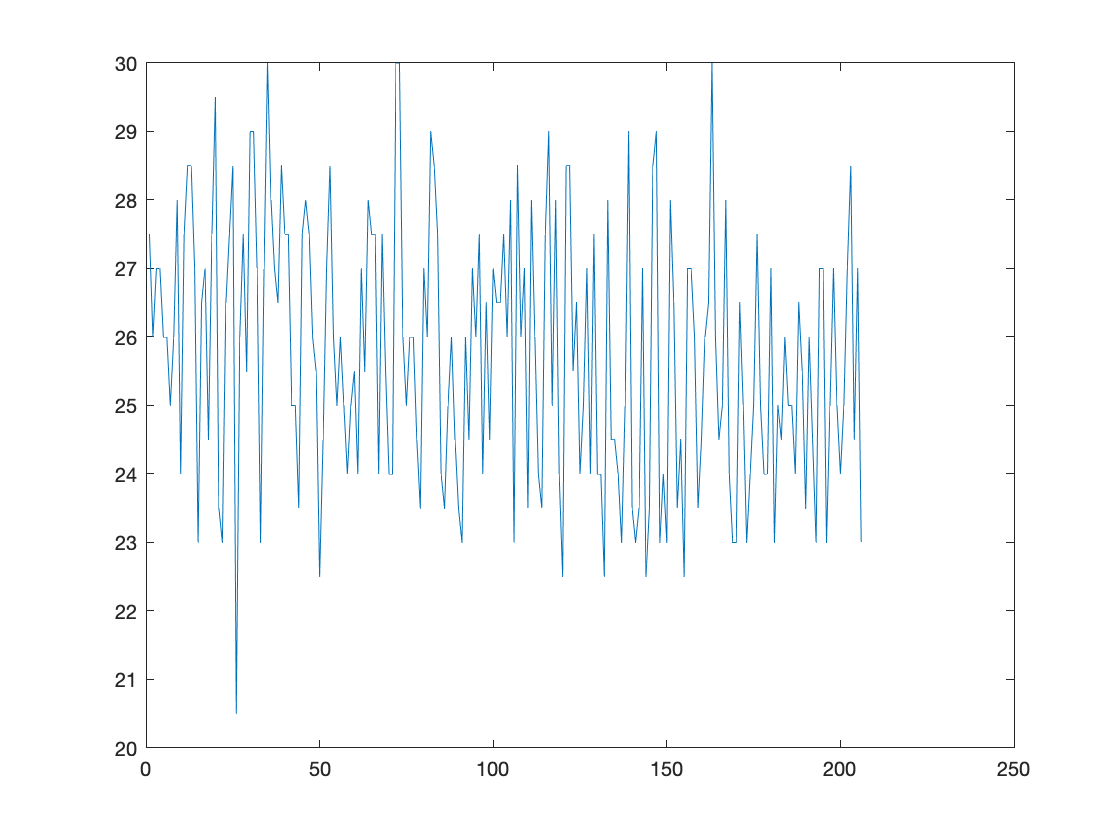

plot(talla)


mEstatura = mean(estatura)

mEstatura = 167.1553

mTalla = mean(talla)

mTalla = 25.7451

dEstatura = std(estatura)

dEstatura = 9.4655

dTalla = std(talla)

dTalla = 1.9138


sTalla = sort(talla);
sEstatura = sort(estatura);


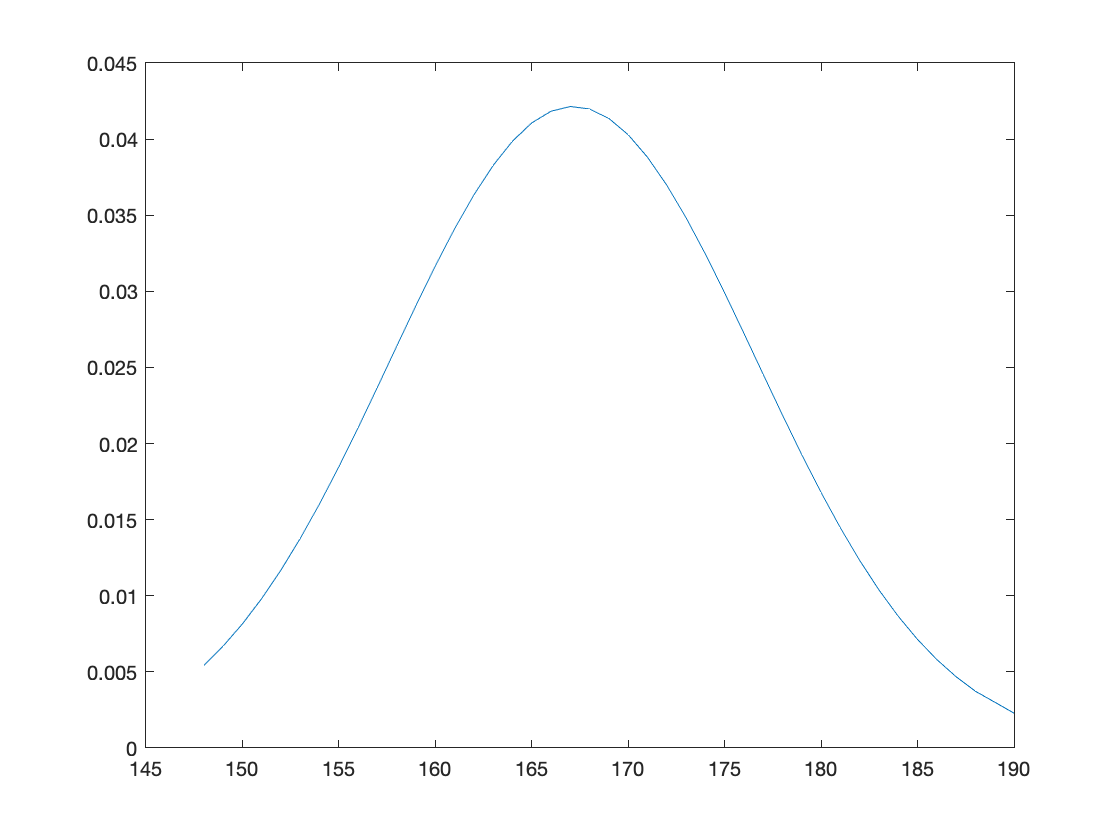

normEstatura = 1/(dEstatura*sqrt(2*pi))*exp(-(sEstatura-mEstatura).^2/(2*dEstatura^2));
normTalla = 1/(dTalla*sqrt(2*pi))*exp(-(sTalla-mTalla).^2/(2*dTalla^2));
plot(sEstatura,normEstatura)

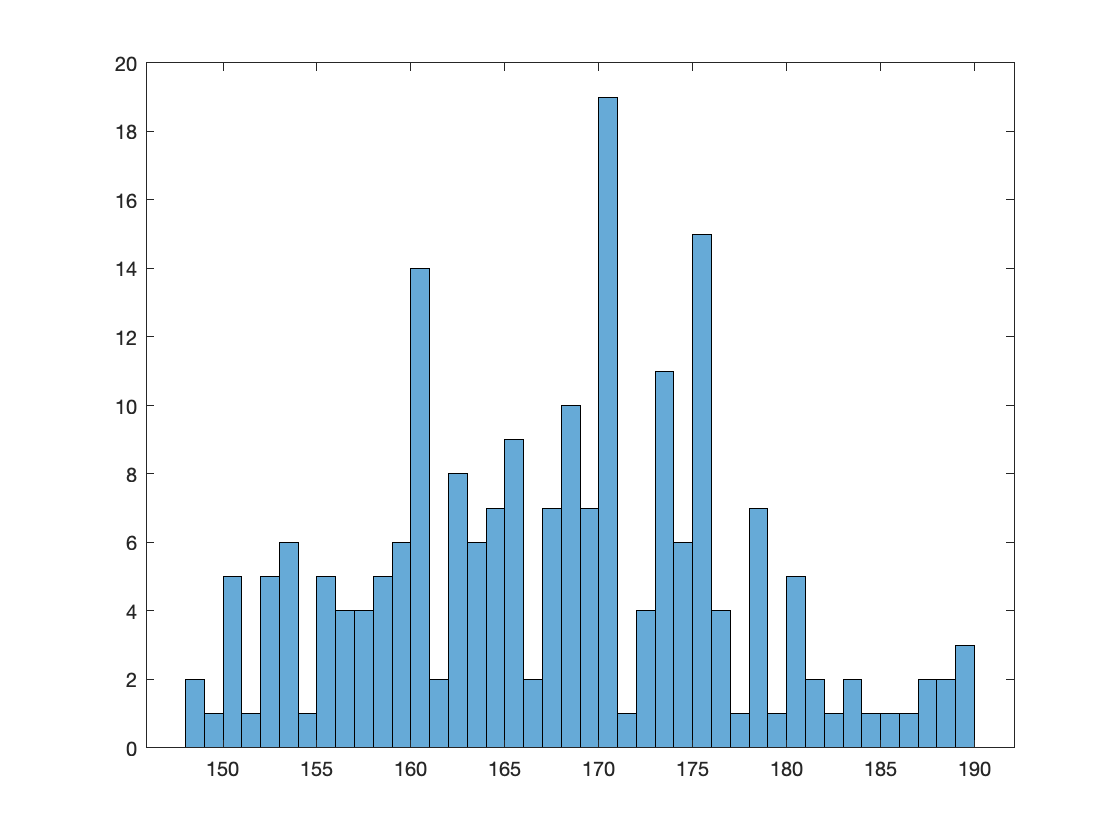

histogram(sEstatura,length(unique(sEstatura)))

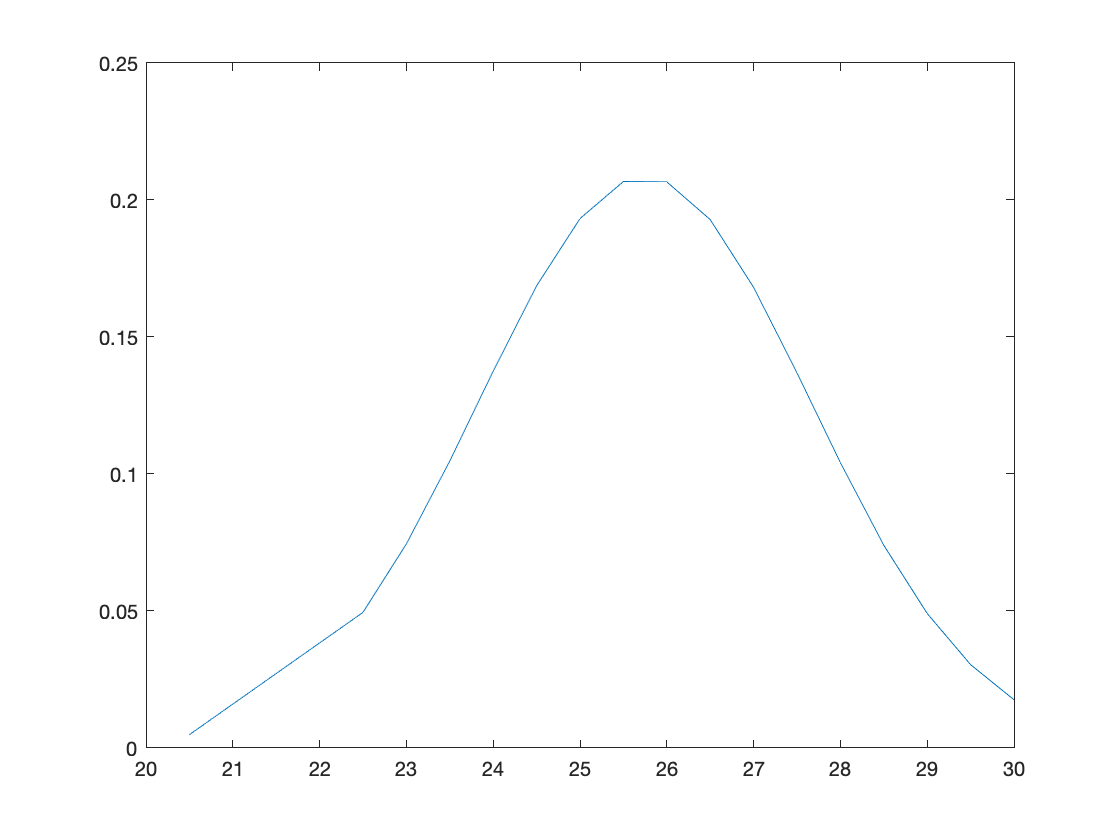

plot(sTalla,normTalla)

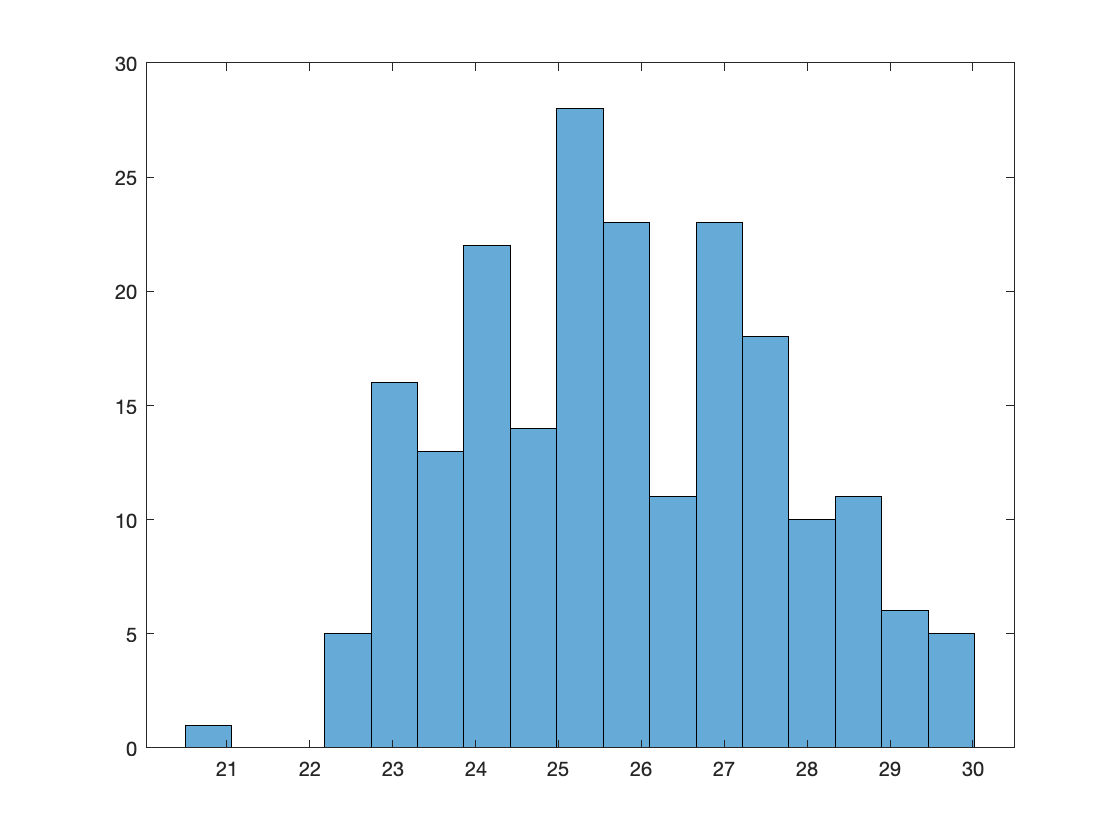

histogram(sTalla,length(unique(sTalla)))

relation = sortrows([estatura talla]);

fitr = fit(relation(:,1),relation(:,2),'poly1')

fitr =      Linear model Poly1:
     fitr(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1618  (0.1451, 0.1785)
       p2 =      -1.299  (-4.102, 1.503)

sx = 1:206;
for i = 1:206
    if sexo(i)=="Masculino"
        sx(i) = 0;
    else
        sx(i) = 1;
    end
end

nMujeres = sum(sx==1);
seg = sortrows([sx' estatura talla]);
masc = seg(1:nMujeres,2:3);
fem = seg(nMujeres:206,2:3);
fitmasc = fit(masc(:,1),masc(:,2),'poly1')

fitmasc =      Linear model Poly1:
     fitmasc(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1177  (0.08598, 0.1493)
       p2 =       6.777  (1.275, 12.28)

fitfem = fit(fem(:,1),fem(:,2),'poly1')

fitfem =      Linear model Poly1:
     fitfem(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1107  (0.08725, 0.1341)
       p2 =       6.523  (2.744, 10.3)

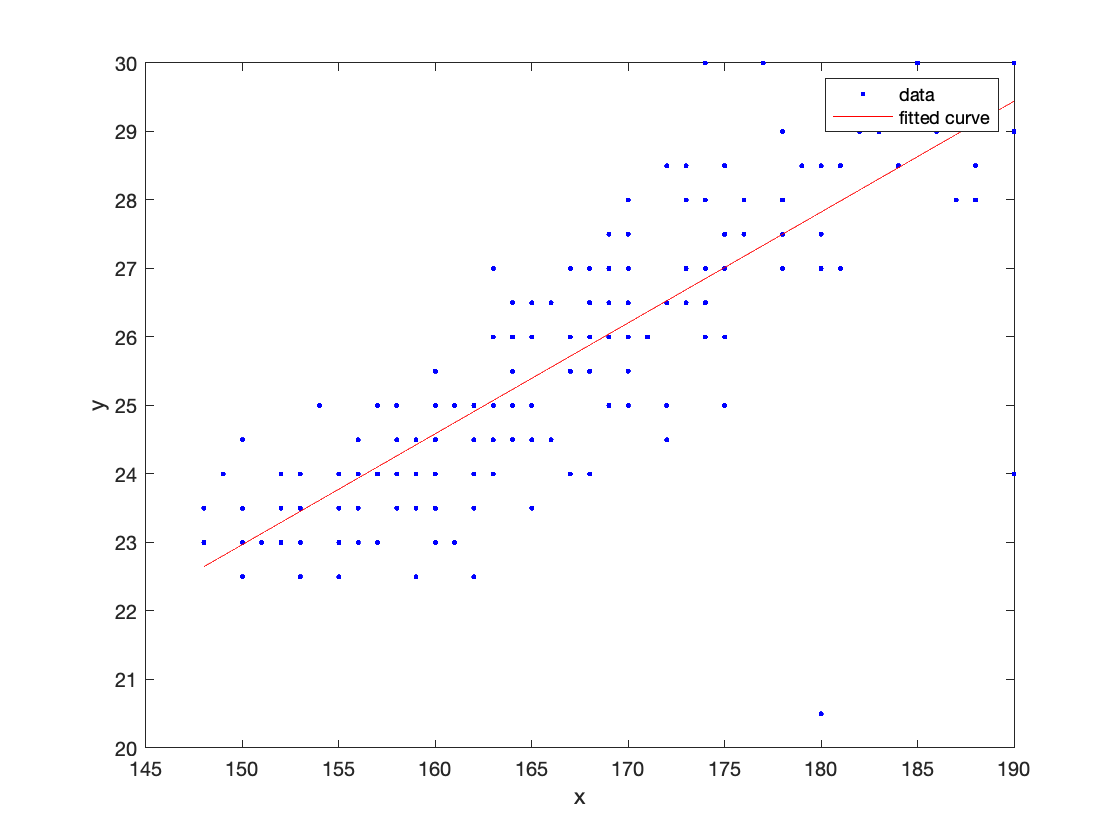

plot(fitr,relation(:,1),relation(:,2))

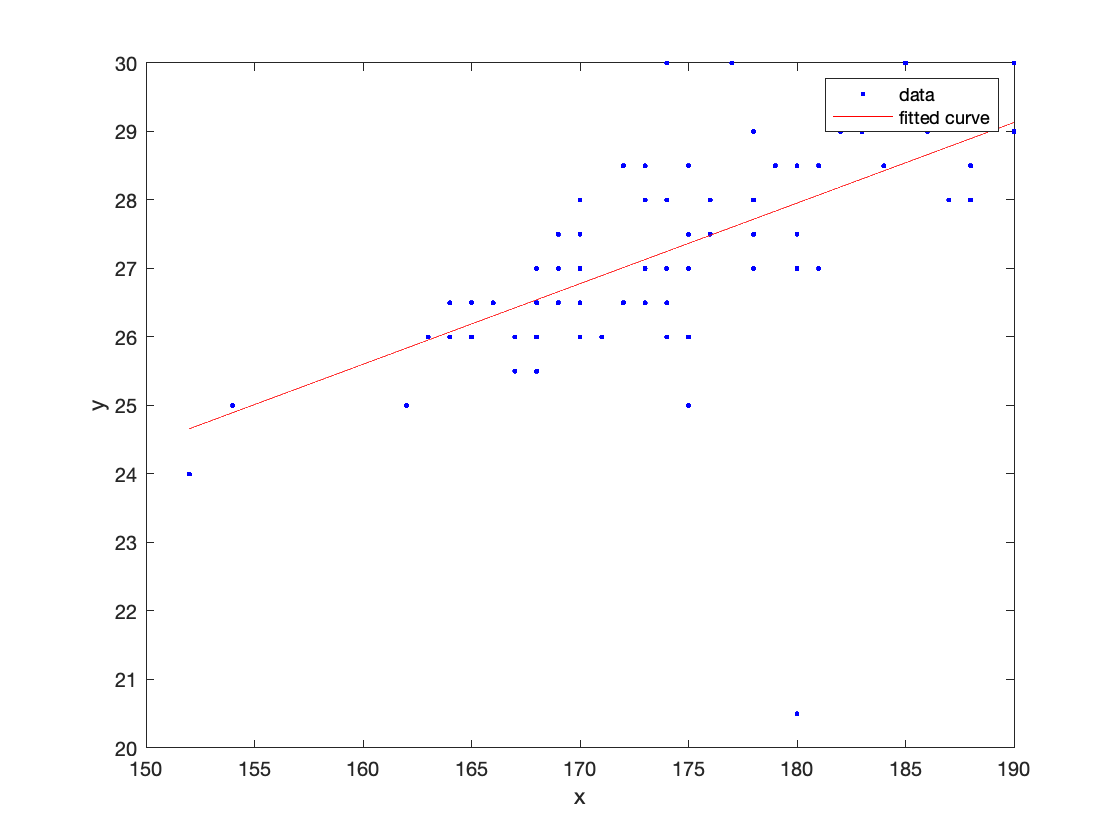

plot(fitmasc,masc(:,1),masc(:,2))

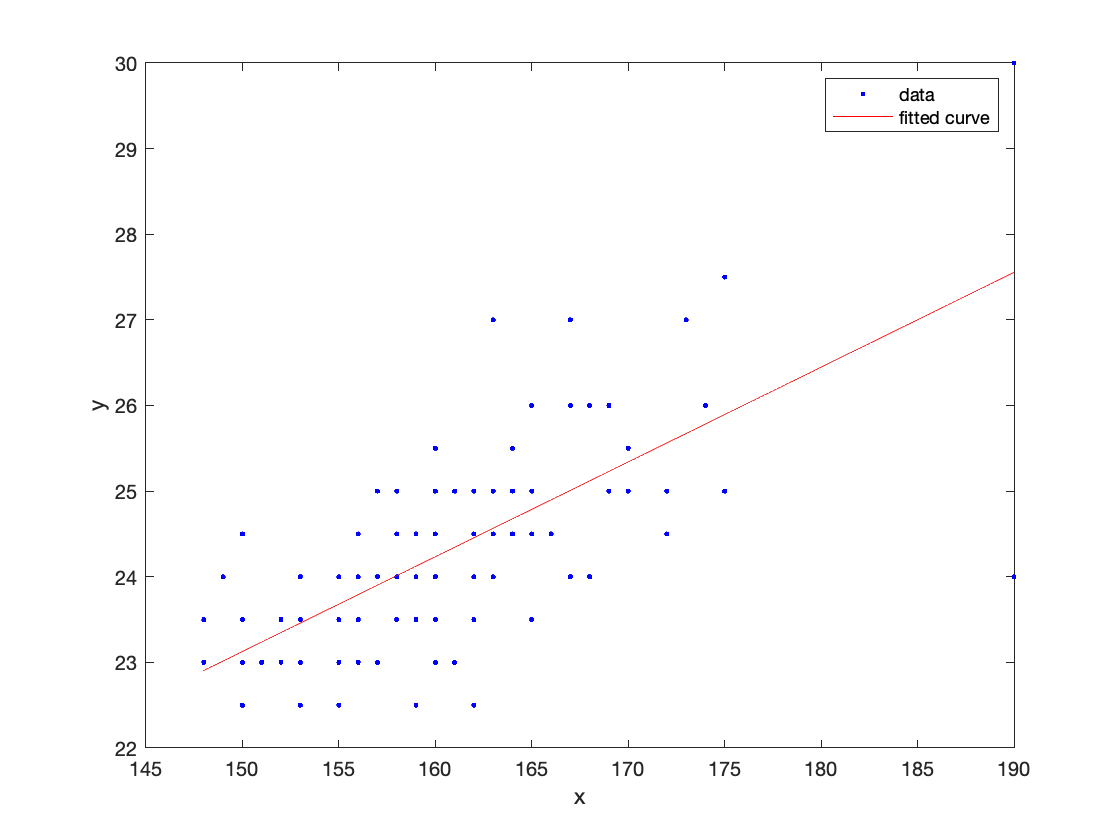

plot(fitfem,fem(:,1),fem(:,2))